Semi-Definite programming Multicretiria

clear all
close all

% Constants
global A;
global b;
A = [2 1; 1 1];
b = [1; 0];
alpha = 0.5; % Pareto parameter

SDP solution to the problem

res = findOptimumSDP(alpha);


 num. of constraints =  3
 dim. of sdp    var  =  5,   num. of sdp  blk  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.5e+00|6.4e+00|5.0e+02| 4.000000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|1.5e-06|6.9e-02|4.3e+01| 3.140567e+01 -8.025413e+00| 0:0:00| chol  1  1 
 2|0.996|0.989|8.4e-08|7.6e-03|4.4e-01| 1.782227e-01 -2.408416e-01| 0:0:00| chol  1  1 
 3|0.989|0.989|1.7e-08|7.6e-04|4.8e-03|-1.628599e-01 -1.663286e-01| 0:0:00| chol  1  1 
 4|0.988|0.989|1.2e-09|7.6e-05|5.5e-05|-1.666226e-01 -1.665482e-01| 0:0:00| chol  1  1 
 5|0.985|0.989|2.0e-10|8.1e-07|7.9e-07|-1.666660e-01 -1.666654e-01| 0:

fprintf("SDP solution: \n")

SDP solution: 


disp(res)

    0.3333
    0.0000
    0.1667



Quadratic Programming solution

res = findOptimumQuadrProg(alpha);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


fprintf("Quadratic-Prog solution: \n")

Quadratic-Prog solution: 


disp(res)

    0.3333
    0.0000



Analytical Solution

beta = (1- alpha)/(alpha);
x = inv(A'*A + beta*eye(2))*A'*b;
fprintf("Analytical solution: \n")

Analytical solution: 


disp(x)

    0.3333
         0



Pareto curve in f1, f2 space

a = 0 : 0.01 : 1;
[f1, f2] = arrayfun(@paretoFrontCurve, a);


 num. of constraints =  3
 dim. of sdp    var  =  5,   num. of sdp  blk  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.5e+00|6.9e+00|5.0e+02| 4.000000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|1.5e-06|7.5e-02|4.3e+01| 3.171974e+01 -8.008931e+00| 0:0:00| chol  1  1 
 2|0.996|0.989|8.8e-08|8.2e-03|4.4e-01| 3.457364e-01 -7.743183e-02| 0:0:00| chol  1  1 
 3|0.989|0.989|1.8e-08|8.3e-04|4.8e-03| 3.798193e-03  1.383463e-04| 0:0:00| chol  1  1 
 4|0.989|0.989|5.4e-11|8.3e-05|5.2e-05| 4.173824e-05  1.004196e-04| 0:0:00| chol  1  1 
 5|0.989|0.989|1.6e-10|9.1e-07|5.8e-07| 4.586614e-07  1.103319e-06| 0:

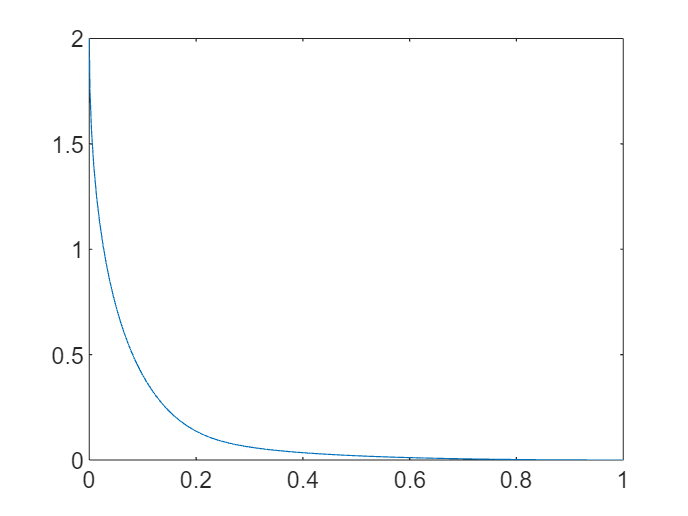

figure(1)
plot(f1, f2)

title('Pareto-Front')
xlabel('|x|^2')
ylabel('|Ax-b|^2')


Functions Used Defined Here

function res = findOptimumSDP(a)
    global A;
    global b;
    % Variables to find during optimization
    t = sdpvar(1);
    x = sdpvar(2, 1);
    % Objective Function
    F = t;
    % Constraints
    A1 = eye(4);
    C = [sqrt(a) * (A*x -  b); sqrt(1 - a)*x];
    B = t;
    LMI = [A1 C; C' B]; % Shur lemma
    constr = LMI >= 0; % vector of constraints
    %Settings
    opts = sdpsettings('solver', 'sdpt3', 'sdpt3.maxit', 55);
    optimize(constr, F, opts);
    res = value([x; t]);
end

function res = findOptimumQuadrProg(a)
    global A;
    global b;
    beta = (1-a)/a;
    %H = 2*(a*A'*A + (1-a)*eye(2));
    %f = 2*a*(b'*A);
    % it's possible to simplify qudratic problem by dividing objective
    % function by the same number (constants added to objective function also doesn't effect the extremum)
    H = A'*A + beta*eye(2);
    f = - b'*A;
    res = quadprog(H, f);
end

function [f1, f2] = paretoFrontCurve(a)
    global A;
    global b;
    res = findOptimumSDP(a);
    x = res(1:2);
    f1 = norm(A*x - b)^2;
    f2 = norm(x)^2;
end